# How to observe a fluid?

[⇦ Overview](matlab:open('./Overview.m'))

Fluid mechanics is the branch of mechanics, the behavior of liquids and gases, the force in action, and their motions. 

[Catchy image]

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon  at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://www.mathworks.com/learn/tutorials/matlab-onramp.html), a free 2 hour online tutorial that teaches the essentials of MATLAB.

## **Two point of view on fluid flow**

### **The Lagrangian point of view**

With the Lagrangian point of view, the observer is specifying the fluid flow by following individual fluid parcels throw time. It is the same point of view that is generaly in classical solid mechanics. You might remember from your kinetmatic course that to characterize the motion of a solid in space, it often suffices to only track the motion associated to one of the point of this solid. The mathematical description of a flow using Lagrangian point of view is composed of many function such as ${\bf X}_{\bf x_0}(t)$, which tracks the position of a fluid parcel with respect to time. In this case, the subscript ${\bf x_0}$ identify the fluid parcel being observe by specifying its initial position.

**Motivating Example: Ocean Drift barge**

The Lagrangian Drifter Laboratory (LDL) [1] is a part of the National Ocenic and Atmospheric Administration (NOAA) that has been focusing for over 40 years in the deployment of a fleet of drifter in every oceans around the world. This array of now over 1,300 drifter provides crucial data for the climate analysis and forecasting, especially for the in-situ investigation of Atlantic hurricanes.

The following data has been gathered from the LDL global drifter database of 2022 Atlantic hurricanes [2]. To visualize the data select the platform code of one of the drifter that have been observed in 2022 around the coast of the United States. The possible set of platform available for visualization has been reduced for optimal results.

% Select a drifter
MyDrifter = 4402877;

load BuoyAndDrifterData.mat DrifterData   
MyDrifterData = DrifterData( DrifterData.platform_code == MyDrifter, :)

MyDrifterData = 984×3 timetable
            time            platform_code    latitude    longitude
    ____________________    _____________    ________    _________
    20-Aug-2022 14:34:00     4.4029e+06       40.361      -68.197 
    20-Aug-2022 15:00:00     4.4029e+06       40.357      -68.201 
    20-Aug-2022 16:04:00     4.4029e+06       40.356      -68.214 
    20-Aug-2022 17:00:00     4.4029e+06       40.356      -68.222 
    20-Aug-2022 19:00:00     4.4029e+06       40.363      -68.241 
    20-Aug-2022 21:00:00     4.4029e+06       40.378      -68.253 
    20-Aug-2022 22:00:00     4.4029e+06       40.384      -68.253 
    20-Aug-2022 23:00:00     4.4029e+06       40.384       -68.25 
    21-Aug-2022 00

% Retime timetable
newMyDrifterData = retime(MyDrifterData,"regular","mean","TimeStep",caldays(1))

newMyDrifterData = 53×3 timetable
       time        platform_code    latitude    longitude
    ___________    _____________    ________    _________
    20-Aug-2022     4.4029e+06       40.367      -68.229 
    21-Aug-2022     4.4029e+06       40.346      -68.317 
    22-Aug-2022     4.4029e+06       40.301      -68.428 
    23-Aug-2022     4.4029e+06       40.278      -68.504 
    24-Aug-2022     4.4029e+06       40.256      -68.587 
    25-Aug-2022     4.4029e+06       40.226      -68.705 
    26-Aug-2022     4.4029e+06       40.193      -68.823 
    27-Aug-2022     4.4029e+06       40.152      -68.908 
    28-Aug-2022     4.4029e+06       40.129      -68.944 
    29-Aug-2022     4.

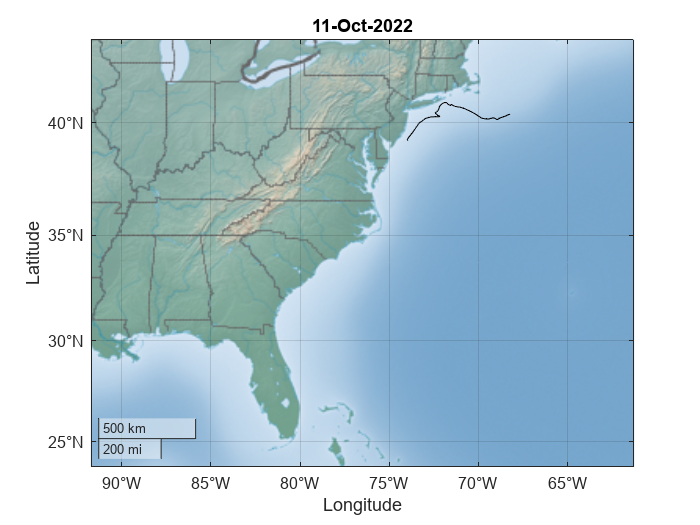

plotDrifter(newMyDrifterData)

Lagrangian experimentation are advantageous because they provide in-situ data. For example, the drifter data gathered the longitude and lattitude of the drifter at different point in time. Considering that the drifter is moving along with the oceanic surface current, we can find the velocity of the current by taking the derivative of the distance travelled with respect to time:

[~, DistNM] = legs(newMyDrifterData.latitude, newMyDrifterData.longitude, "rh");
DistKM = nm2km(DistNM);

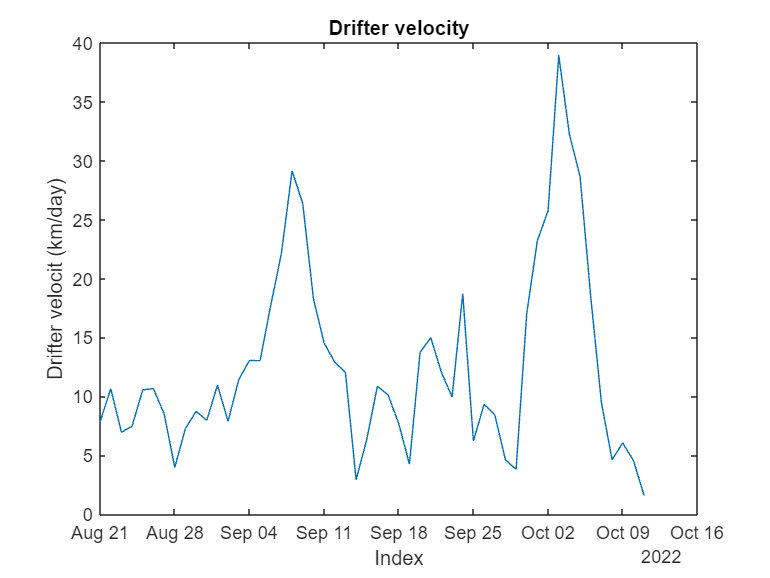

figure
plot(newMyDrifterData.time(2:end),DistKM)
xlabel('Index')
ylabel('Drifter velocit (km/day)')
title('Drifter velocity')

 **Reflect**. How convenient is the Lagrangian point of view?

If you have not done so already, take a look at the drifter identified by platform 4402877. In April 2022, this drifter begin its journey from the Gulf of Mexico to the Atlantic Ocean before to beach on the Atlantic coast of Florida in early May 2022. Further experimentation using this drifter would require retrieval and re-launch in the ocean. 

### The Eulerian point of view

Unlike the Lagrangian point of view, the Eulerian point of view does not rely on following the fluid particle. In place, it observe the physical quantity at a location in space. In most Eulerian observation, the point of spatial observation point are often fixed. The fluid flow is mathematically described uising field function such as ${\bf u}({\bf x}, t)$ where ${\bf x}
$ refer to a physical point in space.

**Motivating Example: Ocean Buoy**

load BuoyAndDrifterData.mat BuoyData
BuoyData

BuoyData = 39380×6 timetable
            DATE            DEP01    DIR01    SPD01     LAT        LON      BOUY 
    ____________________    _____    _____    _____    ______    _______    _____
    01-Jan-2021 00:04:00      2       244      7.7     42.523    -70.566    44029
    01-Jan-2021 01:04:00      2       209     13.6     42.523    -70.566    44029
    01-Jan-2021 02:04:00      2       235     19.8     42.523    -70.566    44029
    01-Jan-2021 03:04:00      2       235     18.1     42.523    -70.566    44029
    01-Jan-2021 04:04:00      2       234     18.9     42.523    -70.566    44029
    01-Jan-2021 05:04:00      2       216     13.5     42

[BuoyID, idxBuoyID] = unique(BuoyData.BOUY)

BuoyID =        44029
       44030
       44032
       44033
       44034


idxBuoyID =            1
        7486
       15005
       23114
       31238


Buoys = BuoyData(idxBuoyID,:)

Buoys = 5×6 timetable
            DATE            DEP01    DIR01    SPD01     LAT        LON      BOUY 
    ____________________    _____    _____    _____    ______    _______    _____
    01-Jan-2021 00:04:00      2       244      7.7     42.523    -70.566    44029
    01-Jan-2021 00:04:00      2        17     15.9     43.179    -70.426    44030
    01-Jan-2021 00:04:00      2        97     19.9     43.715    -69.355    44032
    01-Jan-2021 00:04:00      2       279      5.4     44.055    -68.996    44033
    01-Jan-2021 00:04:00      2        64     16.1     44.103    -68.112    44034

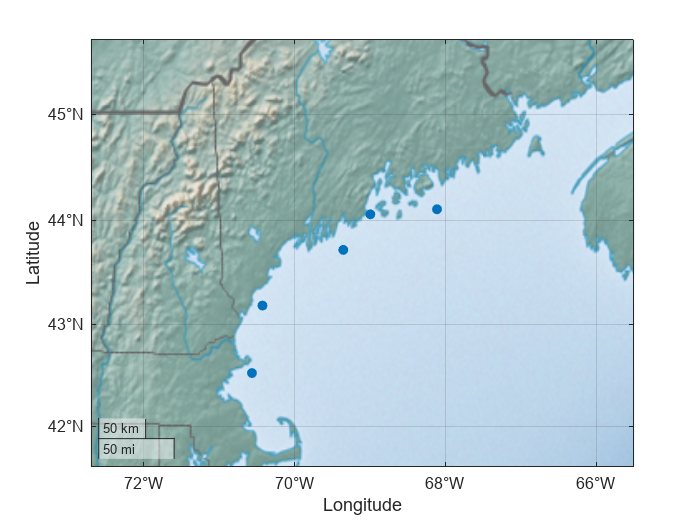

figure
geoscatter(Buoys,"LAT","LON","filled","SeriesIndex",1)
geobasemap colorterrain
geolimits([41.6 45.7],[-72.7 -65.5])

MyBuoyData = BuoyData( BuoyData.BOUY == MyBuoy, :)

MyBuoyData = 8124×6 timetable
            DATE            DEP01    DIR01    SPD01     LAT        LON      BOUY 
    ____________________    _____    _____    _____    ______    _______    _____
    01-Jan-2021 00:04:00      2       279      5.4     44.055    -68.996    44033
    01-Jan-2021 01:04:00      2       299     13.9     44.055    -68.996    44033
    01-Jan-2021 02:04:00      2       305     19.2     44.055    -68.996    44033
    01-Jan-2021 03:04:00      2       273      9.9     44.055    -68.996    44033
    01-Jan-2021 04:04:00      2       216     16.8     44.055    -68.996    44033
    01-Jan-2021 05:04:00      2       261     13.3     4

MyBuoy = 44033;
MyBuoyData = BuoyData(BuoyData.BOUY == MyBuoy,:)

MyBuoyData = 8124×6 timetable
            DATE            DEP01    DIR01    SPD01     LAT        LON      BOUY 
    ____________________    _____    _____    _____    ______    _______    _____
    01-Jan-2021 00:04:00      2       279      5.4     44.055    -68.996    44033
    01-Jan-2021 01:04:00      2       299     13.9     44.055    -68.996    44033
    01-Jan-2021 02:04:00      2       305     19.2     44.055    -68.996    44033
    01-Jan-2021 03:04:00      2       273      9.9     44.055    -68.996    44033
    01-Jan-2021 04:04:00      2       216     16.8     44.055    -68.996    44033
    01-Jan-2021 05:04:00      2       261     13.3     4

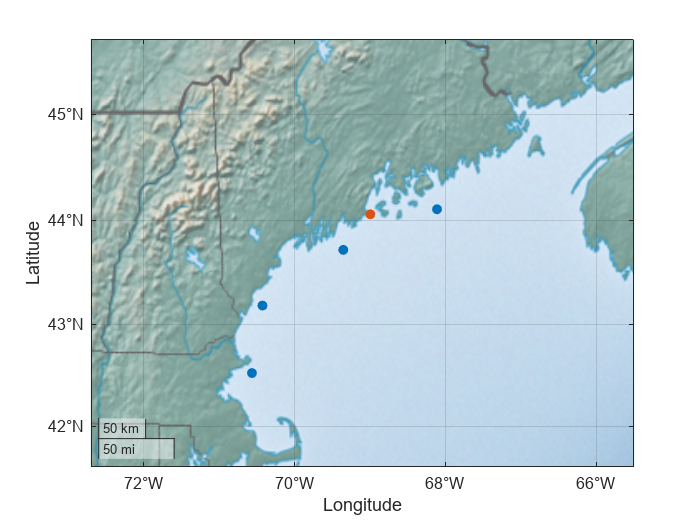

shold on
geoscatter(MyBuoyData(1,:),"LAT","LON","filled","SeriesIndex",2)
hold off

% Retime timetable
newMyBuoyData = retime(MyBuoyData,"regular","mean","TimeStep",caldays(1))

newMyBuoyData = 365×6 timetable
       DATE        DEP01    DIR01     SPD01      LAT        LON      BOUY 
    ___________    _____    ______    ______    ______    _______    _____
    01-Jan-2021      2      230.29    24.317    44.055    -68.996    44033
    02-Jan-2021      2      216.75    44.142    44.055    -68.996    44033
    03-Jan-2021      2      165.96    60.117    44.055    -68.996    44033
    04-Jan-2021      2      177.12    49.262    44.055    -68.996    44033
    05-Jan-2021      2      164.67    63.304    44.055    -68.996    44033
    06-Jan-2021      2      169.21    54.733    44.055    -68.996    44033
    07-Jan-2021

## Why does it matter?

The laws of physics apply the the particle not the grid and because the Eulerian 

## Material derivative

 **Reflect**. The second law of physics tell us $m\frac{\;\partial \mathit{\mathbf{u}}}{\partial t}=\mathit{\mathbf{F}}$

A    Phi(x,t)

B    Phi(x+u*dt, t+dt)

% syms Phi(x,t) u dx dt
% 
% dPhidt = limit( ( Phi(x+u*dt, t+dt) - Phi(x,t) )/dt, dt, 0 )



$$\frac{D\phi \;}{\textrm{Dt}}=\frac{\;\partial \phi \;}{\partial t}+\mathit{\mathbf{u}}\cdot \nabla \phi \;$$


% [graduxx, graduxy] = gradient(ux, 0.1);
% [graduyx, graduyy] = gradient(uy, 0.1);
% Ax = 0.0 + ux.*graduxx + uy.*graduxy;
% Ay = 0.0 + ux.*graduyx + uy.*graduyy;
% A  = sqrt(Ax.^2+Ay.^2);
% contourf(xg, yg, A , 256, 'LineColor', 'none')
% hold on
% quiver(xg, yg, Ax, Ay, 'Color', 'w')
% xlim([0 1])
% ylim([0 1])
% xlabel("x-location")
% ylabel("y-location")
% title("Total derivative of velocity")
% hold off

 **Reflect**.This acceleration is the acceleration felt by the particle of fluid in this field of velocity. Newton's law $m\vec{a} =\sum \vec{\;F_{\textrm{ext}\;} }$

Physical properties of the system such as temperature, mass, density, or really anything is hold on the fluid particle wether than the grid.

## Reynolds Transport Theorem

So far we discussed how to describe the motion of the fluid particle


$$\int(\nabla\cdot {\bf F})dV=\int ({\bf F}\cdot{\bf n})dS$$


1 - Derive the Reynolds transport therorem

2 - Ask to apply the theorem to mass -> conservation of mass

3 - Conservation of energy?

% 

## References

[1] The Lagrangian Drifter Laboratory [website](https://gdp.ucsd.edu/ldl/)

[2] Global Drifter Program Atlantic Hurricane 2022 [Data](https://drifterdata.ucsd.edu/erddap/tabledap/GDP_AtlanticHurricane2022.html)

## Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

function plotDrifter(MyDrifter)
        
    figure
    geoaxes
    geolimits([23.7 43.5],[-91.6975 -61.3025])
    geobasemap colorterrain
    
    numDataPoint = size(MyDrifter, 1);

    h = animatedline;
    for i = 1:numDataPoint;
        addpoints(h, MyDrifter.latitude(i), MyDrifter.longitude(i))
        title( string(MyDrifter.time(i)) )
        drawnow
    end

end

function plotBouy(Bouy)
    figure
    pax = polarplot(NaN, NaN);
    pax.Parent.Parent = f1;
    pax.Parent.ThetaDir = "clockwise";
    pax.Parent.ThetaZeroLocation = "top";
    pax.Parent.ThetaTick = 0:45:360;
    pax.Parent.ThetaTickLabel = {'N', 'NE', 'E', 'SE', 'S', 'SW', 'W', 'NW'};
    pax.Parent.Position = [0.650 0.150 0.225 0.30];
    pax.Parent.RTick = [50 100 150];
    pax.Parent.RLim = [0 150];
    h = animatedline(pax.Parent, 'LineStyle', '-', 'LineWidth', 2);
    
    % Reduce dataset to the selected bouy data:
    bouy = bouy( bouy.BOUY == Bouy, :);
    bouy = sortrows(bouy, "DATE", "ascend");
    for i = 1:size(bouy,1)
        clearpoints(h)
        addpoints(h,  [0 bouy.DIR01(i)], bouy.SPD01(i)*[0 1])
        title(geop.Parent, string(bouy.DATE(i)))
        if ( mod(i,50) == 0 )
            drawnow
        end
    end
end

[⇦ Return to the navigation page](matlab: OpenOverview)